# Project 1 MA 493 

Authored: Sarah Bird (The Do-er), Nicholas Gawron (Group Parent), Jamie Loring (The Facilitator), Andrea Stancescu (The Caffeinated)

Date: 3/4/2022 

# Part I: K++ Initalization 

### Concept

Clear the workspace and close all figure windows

clear all
close all
clc

Load the data for this question

load Q1data.mat

## **a) random initialization by sampling components using a uniform distribution for each component on the interval [-1.2, 1.2] **

Set the number of data vectors (n) and the dimension of the data space (m)

[n,m] = size(XData);

Set the number of clusters (k)

k=5;

Assign each data vector, randomly to one of the k clusters

IndexSet = randi(k,n,1);

Plot the data

scatter(XData(:,1),XData(:,2),64,IndexSet,'filled');
hold on

Create data structures to store the weight vectors for cluster (c), and the weight vectors from the previous iteration (cPrev)

c = zeros(k,m);
cPrev = zeros(k,m);

Randomly initialize the weight vectors so that each component is sampled from the interval [-1.2,1.2]

c = -1.2 + 2.4*rand(k,m);

Plot the initial weight vectors

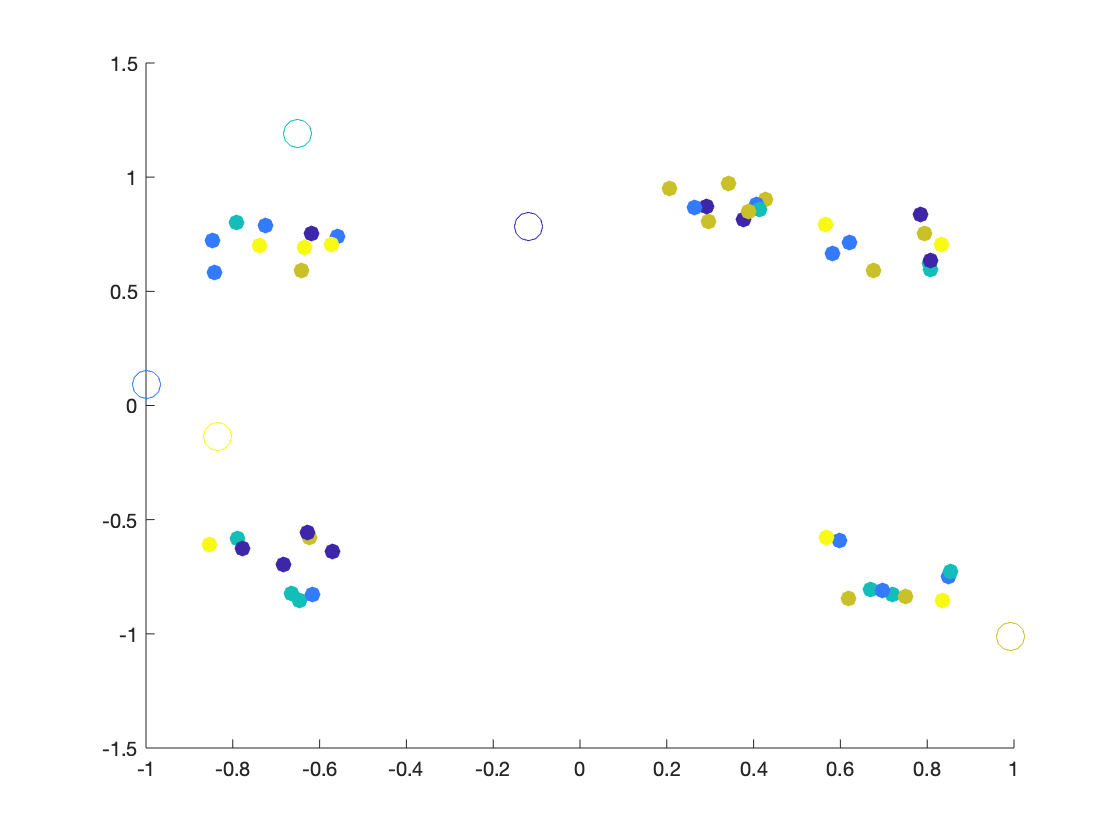

scatter(c(:,1),c(:,2),200,linspace(1,k,k))
hold off

pause

### **The Alternating Minimization Scheme**

Calls the function that will perform the Alternating Minimization Scheme.

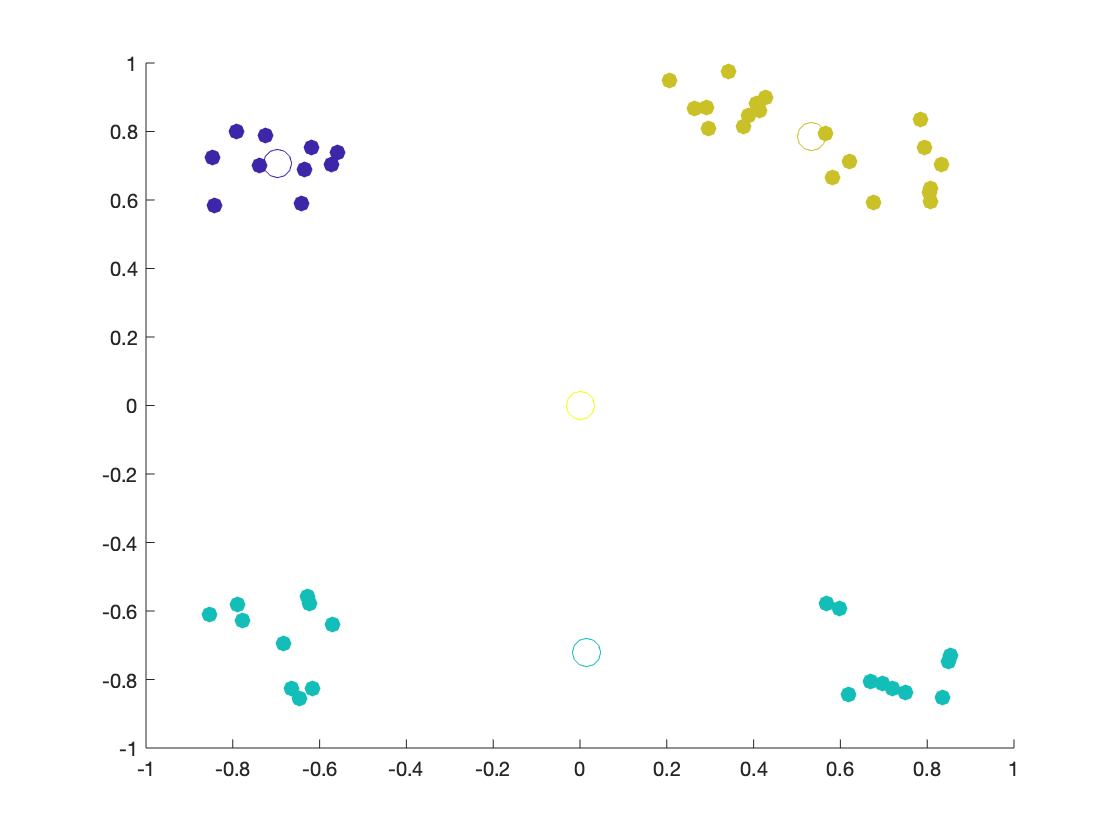

[IndexSetf,cf]=kmeans493(XData,k,IndexSet,c)

## b) the k++ initialization outlined in the project instructions

Calls the function that will perform the k++ initialization.

[ci,IndexSeti]= KPlusPlusInit(XData,k)

c =    -0.5589    0.7385
    0.8342   -0.8533
   -0.6645   -0.8255
    0.8339    0.7048
    0.2060    0.9495


IndexSeti =      1
     5
     1
     4
     5
     5
     1
     2
     2
     5


### Applying the Initalization 

#### 10 Realizations of K-Means 

### Conclusions

## Part II: Elbow Method

### Generalized Code

### Discussion on Optimal $k$ per Inialization

## Part III: MNIST Application 

## Part IV: Bonus

### Functions

KPlusPlusInIt: "description"

function [c,IndexSeti]= KPlusPlusInit(XData,k)

% returns the k num of clusters in the matrix c 

% IndexSeti is the inital clustering 

[n,m]=size(XData);

% Establishes Index Set
% first is the inital index set
IndexSeti = randi(k,n,1);
IndexSet = IndexSeti;

% Haider likes zero initalization! 
c = zeros(k,m);


%%%%% Gets C_1

% first step of k++
randIndex = randi(n);

% first cluster rep vector!
c(1,:)= XData(randIndex,:);



%%%%% Create a data structure to store closest weight vector for each data
% point
closestCluster=zeros(n,1);


for l = 2:k
    
    % Reassign each data vector to the new, closest cluster
    for d=1:n

        % Store the coordinates of the current data vector
        xD = XData(d,:);

        % Set the minimum distance tracker to be a very large number
        sqDistMin=1e16;

        % Find the closest weight vector (cluster) to the current data
        % vector
        for i=1:l-1
            sqDist = norm(c(i,:)-xD,2);

            % If the distance is less than the current min, assign the
            % current data vector to this cluster
            if sqDist<sqDistMin
                closestCluster(d)=i;
                sqDistMin=sqDist;
            end

        end
    end

    % Update the assignments of the data vectors to their new clusters
    IndexSet = closestCluster;

    % sets up a matrix [distance , data point] for each max dist point per
    % cluster initalizes values to zero!
    DistanceANDClusterCani = zeros(l-1,3);
    
    
    % we have l-1 clusters looking for the l th cluster
    for y = 1:l-1
        % fetches points closest to y-th cluster
        PointsClosest2y = XData(IndexSet ==y,:);
        % computes the distance from closest points to the y-th cluster
        % gets the max!
        % 2 in the sum lets us sum by row!
        [Max_dist_forClosestClus,IndexInClosest] = max (sum( (PointsClosest2y -c(y,:)).^2,2));
        DistanceANDClusterCani(y,:)= [Max_dist_forClosestClus,PointsClosest2y(IndexInClosest,:)];
    end 
    [~, NextCentriodLoc]= max(DistanceANDClusterCani(:,1));
    c(l,:) = DistanceANDClusterCani(NextCentriodLoc,2:end);
end 


end

kmeans493: "description"

function [IndexSetf,cf]=kmeans493(XData,k,IndexSet,c)

[n,m]=size(XData); 

% intialized C_prev 
cPrev = zeros(k,m);

doneFlag=0;

% Keep alternating updates to weight vectors and cluster assignments until weight 
% vectors no longer change their locations

while (~doneFlag)

    % Update the weight vectors in each cluster via the centroid formula
    for i=1:k 

        % Find the indices for all data vectors currently in cluster i
        ClusterIndices = find(IndexSet==i);

        % Find the number of data vectors currently in cluster i
        NumVecsInCluster = size(ClusterIndices,1);

        % Create a data structure to store weight vector for the current
        % cluster
        c(i,:)=0; 

        % Update cluster vector using the centroid formula
        for j=1:NumVecsInCluster
            for l=1:m
                c(i,l) = c(i,l) + XData(ClusterIndices(j,1),l)/NumVecsInCluster;
            end
        end

    end

    % Plot the updated weight vectors for each cluster
    scatter(XData(:,1),XData(:,2),64,IndexSet,'filled')
    hold on
    scatter(c(:,1),c(:,2),200,linspace(1,k,k))
    %pause
    
    % Now reassign all data vectors to the closest weight vector (cluster)

    % Create a data structure to store closest weight vector for each data
    % point
    closestCluster=zeros(n,1);

    % Reassign each data vector to the new, closest cluster
    for d=1:n

        % Store the coordinates of the current data vector
        xD = XData(d,:);

        % Set the minimum distance tracker to be a very large number
        sqDistMin=1e16;

        % Find the closest weight vector (cluster) to the current data
        % vector
        for i=1:k
            sqDist = norm(c(i,:)-xD,2);

            % If the distance is less than the current min, assign the
            % current data vector to this cluster
            if sqDist<sqDistMin
                closestCluster(d)=i;
                sqDistMin=sqDist;
            end

        end
    end

    % Update the assignments of the data vectors to their new clusters
    IndexSet = closestCluster;
    
    % Plot the data and the updated weight vectors
    hold off
    scatter(XData(:,1),XData(:,2),64,IndexSet,'filled')
    hold on
    scatter(c(:,1),c(:,2),200,linspace(1,k,k))
    hold off
    %pause
    
    % Terminate the alternating scheme if the weight vectors are unaltered
    % relative to the previous iteration
    if c==cPrev
        doneFlag=1;
    else
        cPrev=c;
    end
end


cf = c ;
IndexSetf = IndexSet; 
end 